%%establecer los vectores con las variables
d=[0.5 0.5 0.5 0.5 1.5 1.5 1.5 2.5 2.5 2.5 2.5 3.5 3.5 3.5 3.5]

d =     0.5000    0.5000    0.5000    0.5000    1.5000    1.5000    1.5000    2.5000    2.5000    2.5000    2.5000    3.5000    3.5000    3.5000    3.5000


p=[86.1 92.1 64.7 74.7 223.6 202.1 132.9 413.5 231.5 466.7 365.3 493.7 382.3 447.2 563.8]

p =    86.1000   92.1000   64.7000   74.7000  223.6000  202.1000  132.9000  413.5000  231.5000  466.7000  365.3000  493.7000  382.3000  447.2000  563.8000


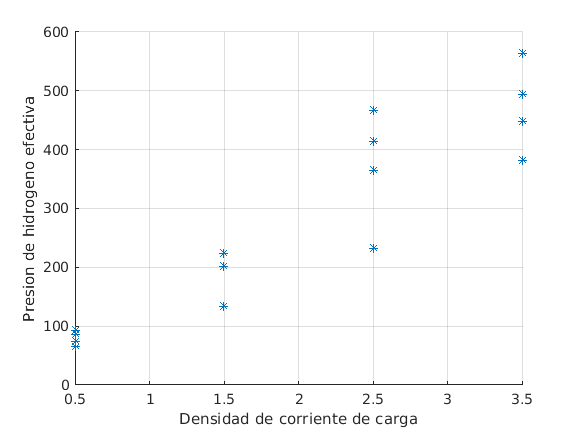


%%graficar diagrama de dispercion
scatter(d,p,'*')
grid on
xlabel('Densidad de corriente de carga')
ylabel('Presion de hidrogeno efectiva')


%%transformacion de modelo exponencial
p1=log(p)

p1 =     4.4555    4.5229    4.1698    4.3135    5.4099    5.3088    4.8896    6.0247    5.4446    6.1457    5.9007    6.2019    5.9462    6.1030    6.3347



%coeficiente de correlacion
r_exp=corrcoef(d,p1)

r_exp =     1.0000    0.9422
    0.9422    1.0000


coeficiente_correlacion_exp=r(2,1)

coeficiente_correlacion_exp = 0.8975


%regresion lineal
n_exp=length(d);
A_exp=[n sum(d); sum(d) sum(d.^2)];
c_exp=[sum(p1); sum(d.*p1)];
solucion_exp=inv(A_exp)*c_exp;
bo_exp=solucion_exp(1);
b1_exp=solucion_exp(2);
syms xa_exp
recta_exp=bo_exp+b1_exp*xa_exp

$$recta\_exp = \frac{170230385409957\,{\mathrm{xa}}_{\exp}}{281474976710656}+\frac{1177044692006883}{281474976710656}$$

xa_exp=d;

%coeficiente de determinacion
r2_exp=sum((eval(recta_exp)-mean(p1)).^2)/sum((p1-mean(p1)).^2)

r2_exp = 0.8877


%%transformacion de modelo de potencias
d2=log10(d)

d2 =    -0.3010   -0.3010   -0.3010   -0.3010    0.1761    0.1761    0.1761    0.3979    0.3979    0.3979    0.3979    0.5441    0.5441    0.5441    0.5441


p2=log10(p)

p2 =     1.9350    1.9643    1.8109    1.8733    2.3495    2.3056    2.1235    2.6165    2.3646    2.6690    2.5626    2.6935    2.5824    2.6505    2.7511



%coeficiente de correlacion
r_pot=corrcoef(d2,p2)

r_pot =     1.0000    0.9579
    0.9579    1.0000


coeficiente_correlacion_pot=r(2,1)

coeficiente_correlacion_pot = 0.8975


%regresion lineal
n_pot=length(d2);
A_pot=[n sum(d2); sum(d2) sum(d2.^2)];
c_pot=[sum(p2); sum(d2.*p2)];
solucion_pot=inv(A_pot)*c_pot;
bo_pot=solucion_pot(1);
b1_pot=solucion_pot(2);
syms xa_pot
recta_pot=bo_pot+b1_pot*xa_pot

$$recta\_pot = \frac{1044318493192881\,{\mathrm{xa}}_{\mathrm{pot}}}{1125899906842624}+\frac{4861505083841293}{2251799813685248}$$

xa_pot=d2;

%coeficiente de determinacion
r2_pot=sum((eval(recta_pot)-mean(p2)).^2)/sum((p2-mean(p2)).^2)

r2_pot = 0.9175